In this live script, I try to add a feature that truncate the iteration (density_matrix_prev) based on a probablity threshold. This could reduce the computational time while not comprising too much the accuracy. I intend to do the following:

- in accumulated_reward_trapezoid.m: add an output that records # of evaluations and test it;

- in accumulated_reward_trapezoid.m: add truncation feature based on an input "trun_prob", so that when density_matrix_prev*Delta <= trun_prob, the current branch is terminated.

- test the added feature and investigate how does it affect the computation time and accuracy.

Throughout this study, we use the same test case as test_numerical_integration_approach.mlx. 

## Numbers of evaluations.

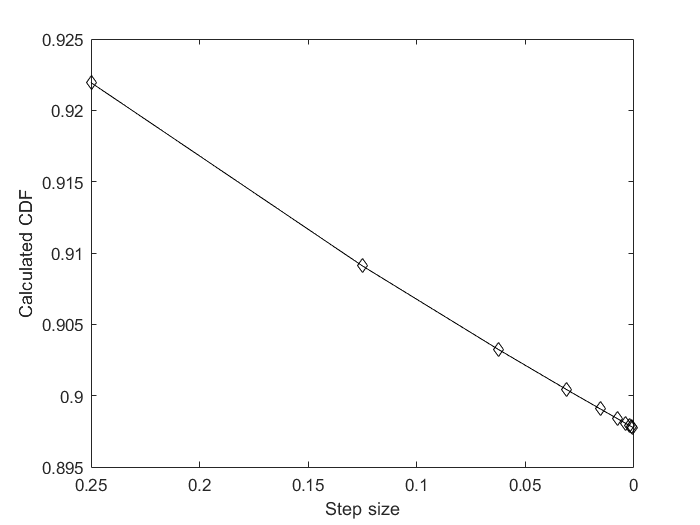

% This is to test the counter for number of evaluations.
clear; clc;
addpath('..\');
addpath('..\trials\');

%% Parameter definition
S = 1:5; % state space
pi = [1,0,0,0,0]; % initial distribution
% Define the Q-matrix
Q = [0,.1,.5,.25,0;...
    1,0,.5,0,.5;...
    0,.25,0,1,.5;...
    1,0,0,0,.5;...
    1,.25,0,1,0];
for i = 1:5
    Q(i,i) = -1*sum(Q(i,:));
end
r = [5,2,4,5,4]; % Reward matrix
% Defining the structure para
para.S = S;
para.pi = pi;
para.Q = Q;
para.r = r;
x_max = 110; % Limit x values
T_max = 25; % Time limit

% %% Calculate P(O(t)>x)
% % Test case 1: T_max = 25, x_max = 110. Theoretical value: 0.89773.
% % Algorithm parameters
% Delta = 1/4*(1/2).^(0:9);
% result_trap = zeros(1,length(Delta));
% elasped_time_trap = zeros(1,length(Delta));
% n_eval_trap = zeros(1,length(Delta));
% for i = 1:length(Delta)
%     fprintf('%d/%d\n',i,length(Delta));
%     tic;
%     [cdf, n_eval] = accumulated_reward_trapezoid_trial(T_max,x_max,Delta(i),para);
%     elasped_time_trap(i) = toc;
%     result_trap(i) = 1 - cdf;
%     n_eval_trap(i) = n_eval;    
% end
% save('result_trun_trap','result_trap','elasped_time_trap','n_eval_trap','Delta');
load('result_trun_trap.mat')

%% Visualize results.
figure;
plot(Delta,result_trap,'kd-');
set(gca,'Xdir','reverse');
xlabel('Step size');
ylabel('Calculated CDF');

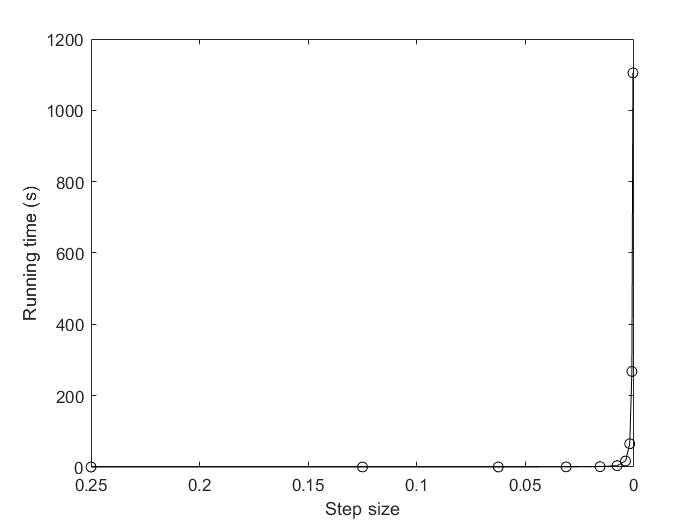


figure;
plot(Delta,elasped_time_trap,'ok-')
set(gca,'Xdir','reverse');
xlabel('Step size');
ylabel('Running time (s)');

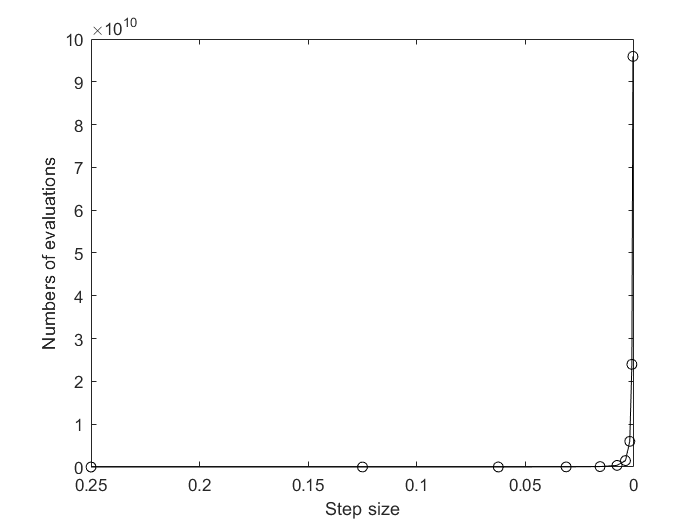

figure;
plot(Delta,n_eval_trap,'ok-')
set(gca,'Xdir','reverse');
xlabel('Step size');
ylabel('Numbers of evaluations');

We also calculate how does the running time, and the number of evaluation changes with step size. It can be seen clearly from the number of evaluation that the computational complexity is propotional to the square of $1/h
$.

[Delta(2:end)./Delta(1:end-1);...
    elasped_time_trap(2:end)./elasped_time_trap(1:end-1);...
    n_eval_trap(2:end)./n_eval_trap(1:end-1)]

ans =      5.000000000000000e-01     5.000000000000000e-01     5.000000000000000e-01     5.000000000000000e-01     5.000000000000000e-01     5.000000000000000e-01     5.000000000000000e-01     5.000000000000000e-01     5.000000000000000e-01
     1.659188600365071e+00     2.264804693969291e+00     3.132670942737904e+00     4.186686157820826e+00     3.754588279686958e+00     4.455328254321448e+00     3.881764714677060e+00     4.108356674477183e+00     4.124064562571188e+00
     4.067881613336159e+00     4.033634895552971e+00     4.016741787311714e+00     4.008352079874735e+00     4.004171349106974e+00     4.002084503419495e+00     4.001041959122746e+00     4.000520906439172e+00     4.000260434942104e+00


## Test the truncation

% %% Calculate P(O(t)>x)
% % Test case 1: T_max = 25, x_max = 110. Theoretical value: 0.89773.
% % Algorithm parameters
% benchmark = .89773;
% Delta = 1/4*(1/2).^(0:9);
% result_trun = zeros(1,length(Delta));
% elasped_time_trun = zeros(1,length(Delta));
% n_eval_trun = zeros(1,length(Delta));
% trun_prob = 1e-12;
% for i = 1:length(Delta)
%     fprintf('%d/%d\n',i,length(Delta));
%     tic;
%     [cdf, n_eval] = accumulated_reward_trapezoid_trial(T_max,x_max,Delta(i),para,trun_prob);
%     elasped_time_trun(i) = toc;
%     result_trun(i) = 1 - cdf;
%     n_eval_trun(i) = n_eval;    
% end
% save('result_trun.mat','result_trun','elasped_time_trun','n_eval_trun','Delta');

load('result_trun.mat');
[result_trap; result_trun]

ans =      9.219429270909529e-01     9.090914502279739e-01     9.032438716093071e-01     9.004467599907119e-01     8.990779813277842e-01     8.984008171832460e-01     8.980640150146628e-01     8.978960556666612e-01     8.978121860253918e-01     8.977702786628917e-01
     9.219429275256340e-01     9.090914511485876e-01     9.032438735251559e-01     9.004467639477386e-01     8.990779894837606e-01     8.984008339635179e-01     8.980640494995447e-01     8.978961264529453e-01     8.978123311914784e-01     8.977705761227058e-01


[elasped_time_trap; elasped_time_trun]

ans =      2.037960000000000e-02     3.381360000000000e-02     7.658120000000000e-02     2.399037000000000e-01     1.004401500000000e+00     3.771114100000000e+00     1.680155120000000e+01     6.521966860000001e+01     2.679456608000000e+02     1.105025204400000e+03
     4.045600000000000e-03     1.324790000000000e-02     4.976380000000000e-02     2.391289000000000e-01     9.204179000000000e-01     4.166866800000000e+00     1.658787830000000e+01     5.694134690000000e+01     2.221292388000000e+02     9.621366170000000e+02


[n_eval_trap; n_eval_trun]

ans =      3.539250000000000e+05     1.439725000000000e+06     5.807325000000000e+06     2.332652500000000e+07     9.350092500000000e+07     3.743937250000000e+08     1.498355325000000e+09     5.994982525000000e+09     2.398305292500000e+10     9.593845772500000e+10
     1.966500000000000e+05     8.421260000000000e+05     3.435147000000000e+06     1.375048700000000e+07     5.455202400000000e+07     2.154001680000000e+08     8.481125610000000e+08     3.332862659000000e+09     1.307700859500000e+10     5.123812368500000e+10


Unfortunately, the truncation-by-probability scheme does not work quite well. To avoid losing too much accuracy, trun_prob needs to be fairly small. But if so, the computational benifit is not very significant.

## Truncate by state aggregation

By a happy error, I discover a more efficient truncation method. The idea is that, at a given time $t_{prev}$, instead of directly calculating all the possible next states, we can make a prediction on if starting from the current state, the final state (accumulated reward <= $x_{max}$) is reachable or not. To do this, note that starting from $t_{prev}$, the maximal possible accumulated reward in the evaluation horizon is $max(r)\cdot (t_{max}-t_{prev})$.  If this maximal value is still less than $x_{max}$, we don't need to consider this state in the iteration, but can directly add its density to calculate $P(\text{accumulated reward} \le x_{max})$. Based this idea, I updated the function accumulated_reward_trapezoid.m and test its performance here.

% This is to test the performance of truncation by state aggregation.
% clear; clc;
% addpath('..\');
% %% Parameter definition
% S = 1:5; % state space
% pi = [1,0,0,0,0]; % initial distribution
% % Define the Q-matrix
% Q = [0,.1,.5,.25,0;...
%     1,0,.5,0,.5;...
%     0,.25,0,1,.5;...
%     1,0,0,0,.5;...
%     1,.25,0,1,0];
% for i = 1:5
%     Q(i,i) = -1*sum(Q(i,:));
% end
% r = [5,2,4,5,4]; % Reward matrix
% % Defining the structure para
% para.S = S;
% para.pi = pi;
% para.Q = Q;
% para.r = r;
% x_max = 110; % Limit x values
% T_max = 25; % Time limit

% %% Calculate P(O(t)>x)
% % Test case 1: T_max = 25, x_max = 110. Theoretical value: 0.89773.
% % Algorithm parameters
% Delta = 1/4*(1/2).^(0:11);
% result_trap = zeros(1,length(Delta));
% elasped_time_trap = zeros(1,length(Delta));
% n_eval_trap = zeros(1,length(Delta));
% for i = 1:length(Delta)
%     fprintf('%d/%d\n',i,length(Delta));
%     tic;
%     [cdf, n_eval] = accumulated_reward_trapezoid(T_max,x_max,Delta(i),para);
%     elasped_time_trap(i) = toc;
%     result_trap(i) = 1 - cdf;
%     n_eval_trap(i) = n_eval;    
% end
% save('result_trun_trap_ac','result_trap','elasped_time_trap','n_eval_trap','Delta');
data = load('result_trun_trap_ac.mat');
result_trap_ac = data.result_trap;
elasped_time_trap_ac = data.elasped_time_trap;
n_eval_trap_ac = data.n_eval_trap;

[result_trap; result_trap_ac(1:10)]

ans =      9.219429270909529e-01     9.090914502279739e-01     9.032438716093071e-01     9.004467599907119e-01     8.990779813277842e-01     8.984008171832460e-01     8.980640150146628e-01     8.978960556666612e-01     8.978121860253918e-01     8.977702786628917e-01
     9.191905073647740e-01     9.076474180744697e-01     9.025095545561619e-01     9.000769801513961e-01     8.988924866145166e-01     8.983079245998924e-01     8.980175331423782e-01     8.978728059248819e-01     8.978005589642056e-01     8.977644645861270e-01


[elasped_time_trap; elasped_time_trap_ac(1:10)]

ans =      2.037960000000000e-02     3.381360000000000e-02     7.658120000000000e-02     2.399037000000000e-01     1.004401500000000e+00     3.771114100000000e+00     1.680155120000000e+01     6.521966860000001e+01     2.679456608000000e+02     1.105025204400000e+03
     1.627570000000000e-02     1.916810000000000e-02     9.027050000000000e-02     1.377396000000000e-01     4.617125000000000e-01     1.776130000000000e+00     8.441422800000000e+00     3.249784710000000e+01     1.389820002000000e+02     6.388915456000000e+02


[n_eval_trap; n_eval_trap_ac(1:10)]

ans =      3.539250000000000e+05     1.439725000000000e+06     5.807325000000000e+06     2.332652500000000e+07     9.350092500000000e+07     3.743937250000000e+08     1.498355325000000e+09     5.994982525000000e+09     2.398305292500000e+10     9.593845772500000e+10
     1.232200000000000e+05     4.984200000000000e+05     2.004820000000000e+06     8.041620000000000e+06     3.221122000000000e+07     1.289344200000000e+08     5.159168200000000e+08     2.064025620000000e+09     8.256819220000000e+09     3.302871042000000e+10


It can be seen that by using this truncation, the computational cost improves roughly $50%. $%. Besides, the result is more close to the theoretical value. This is because, in the original method, all the time points need to be consider, so that the density at the end of the evaluation quickly decreases to a very small values (~$10^{-20}
$). When adding these small numbers together, round-off errors might affect the accuracy. Using the truncation, however, terminates the iteration early before its density becomes too small, and in this way, reduces the round-off errors.

But unfortunately, the computational cost is still proportional to $\frac{1}{h^2}.$

### Implement the new algorithm on accumulated_reward_numit.m

% Numerical integration, do until epsilon <= tol.
addpath('..\');
tol = 1e-4;
format longE;
tic;
[cdf_numit, epsilon_numit] = accumulated_reward_numit(T_max,x_max,Delta,para,tol);
result_numit = 1 - cdf_numit;
elasped_time_numit = toc;
% Load Monte Carlo result.
load('result_benchmark.mat');
NS = 1e7;
% Calculate the cdf
result_MC = sum(P_O_time>x_max)/NS;
% Confidence interval
alpha = .05;
cal_sigma_hat = @(N,p) sqrt(1/(N-1).*(p.*(1-p)));
cal_ci = @(N,p,alpha) [p-norminv(1-alpha/2)*cal_sigma_hat(N,p),...
    p+norminv(1-alpha/2)*cal_sigma_hat(N,p)];
result_MC_CI = cal_ci(NS,result_MC,alpha);
sample_std = cal_sigma_hat(NS,result_MC);
% Compare results.
[result_numit; result_MC]

ans =      8.977383383450198e-01
     8.976969000000000e-01


result_MC_CI

result_MC_CI =      8.975090732809060e-01     8.978847267190940e-01


[elasped_time_numit; elasped_time_MC]

ans =      2.597611600000000e+00
     1.647541618200000e+03


### Test vector of $t$

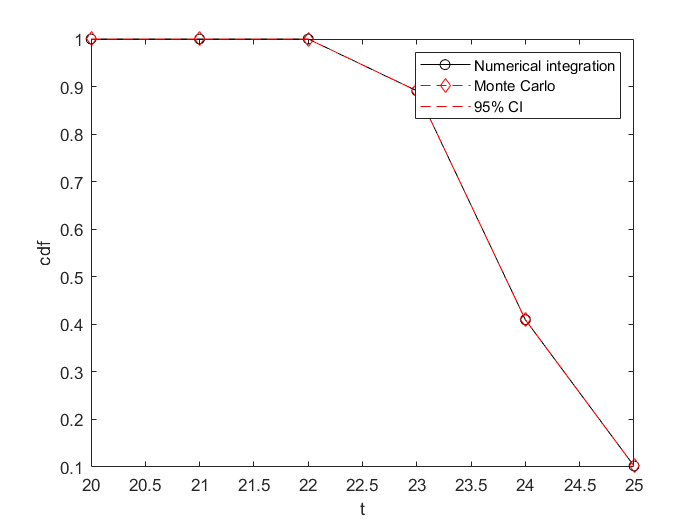

% Test the numerical integration.
tic;
t = 20:25;
[result_numit_t, epsilon_t] = accumulated_reward_numit(t,x_max,Delta,para,tol);
elasped_time_numit_t = toc;
% Load MC result
load('result_benchmark_cdf_t.mat');
% Visualize the results
figure
plot(t,result_numit_t,'-ko');
hold on;
plot(t,cdf_t_MC,'r--d',t,ci_t_MC,'--r');
xlabel('t');
ylabel('cdf');
legend('Numerical integration','Monte Carlo','95% CI');